# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 5;
threshold = 0.6;

## Generate a random physical topology

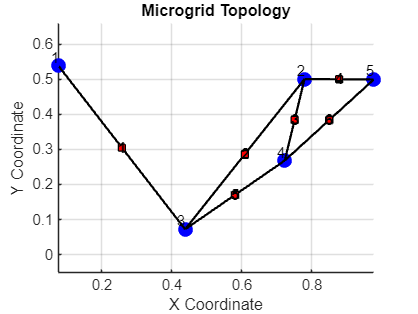

Coordinates of DGs:
    0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999

Adjacency Matrix:
     0     0     1     0     0
     0     0     1     1     1
     1     1     0     1     0
     0     1     1     0     1
     0     1     0     1     0

B_il Matrix:
     1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1



coords =     0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999


A_ij =      0     0     1     0     0
     0     0     1     1     1
     1     1     0     1     0
     0     1     1     0     1
     0     1     0     1     0


B_il =      1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i})
end

PVal =     0.5418    1.7563   -0.2307
    1.7563   10.6295   -0.7673
   -0.2307   -0.7673    0.4001


KVal =   -32.9711    1.4620   -0.2294


LVal =  -150.9331   21.7666  -45.8524


nuVal = -3.4738

rhoVal = 0.2879

status = logical
   1


PVal =     0.5499    1.7631   -0.2334
    1.7631   10.5532   -0.7665
   -0.2334   -0.7665    0.4001


KVal =   -37.2050    1.3946   -0.2276


LVal =  -167.9917   24.4409  -51.7410


nuVal = -3.4334

rhoVal = 0.2913

status = logical
   1


PVal =     0.5621    1.7665   -0.2369
    1.7665   10.4255   -0.7656
   -0.2369   -0.7656    0.4001


KVal =   -16.7087    1.7475   -0.2468


LVal =   -74.3007   11.0307  -23.5078


nuVal = -3.3829

rhoVal = 0.2957

status = logical
   1


PVal =     0.5453    1.7539   -0.2312
    1.7539   10.5915   -0.7674
   -0.2312   -0.7674    0.4001


KVal =   -23.2622    1.4944   -0.2296


LVal =  -105.4095   15.2618  -32.2189


nuVal = -3.4668

rhoVal = 0.2885

status = logical
   1


PVal =     0.5519    1.7604   -0.2336
    1.7604   10.5301   -0.7666
   -0.2336   -0.7666    0.4001


KVal =   -28.4927    1.4680   -0.2316


LVal =  -127.6944   18.6152  -39.4502


nuVal = -3.4319

rhoVal = 0.2914

status = logical
   1


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l})
end

PBarVal = 0.0075

nuBarVal = -1.6328e-10

rhoBarVal = 0.0220

status = logical
   1


PBarVal = 0.0074

nuBarVal = -1.4016e-10

rhoBarVal = 0.0237

status = logical
   1


PBarVal = 0.0092

nuBarVal = -1.3317e-09

rhoBarVal = 0.0237

status = logical
   1


PBarVal = 0.0066

nuBarVal = -2.7473e-11

rhoBarVal = 0.0277

status = logical
   1


PBarVal = 0.0064

nuBarVal = -1.9302e-11

rhoBarVal = 0.0257

status = logical
   1


PBarVal = 0.0068

nuBarVal = -4.3945e-11

rhoBarVal = 0.0245

status = logical
   1


Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 

## Centralized Local Controller Design

BarGamma = 5;    % Fixed value for gammaBar
[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma) % topologyMetrics may be the B matrix 

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 78              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 31              
  Matrix variables       : 16 (scalarized: 273)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1


% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

DG{1}

ans = struct with fields:
              R: 0.0268
              L: 0.0180
              C: 0.0026
              Y: 3.3260
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.0763 0.5385]
             P0: [3×3 double]
             K0: [-127.3038 17.9344 -76.1617]
             nu: -74.5263
            rho: 5.2988
    gammaTilde0: 14.9053


DG{numOfDGs}

ans = struct with fields:
              R: 0.0252
              L: 0.0175
              C: 0.0029
              Y: 3.2822
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.9780 0.4999]
             P0: [3×3 double]
             K0: [-105.6288 15.0042 -65.4971]
             nu: -72.6706
            rho: 5.2962
    gammaTilde0: 14.5341



Line{1}

ans = struct with fields:
      R: 0.0220
      L: 0.0149
      A: -1.4790
      B: 67.0796
     P0: 0.1426
     nu: -20.9931
    rho: -20.5714


Line{numOfLines}

ans = struct with fields:
      R: 0.0245
      L: 0.0135
      A: -1.8129
      B: 73.9110
     P0: 0.1376
     nu: -21.4639
    rho: -20.9650


## Global Controller Design

isSoft = 1; % Set to 1 to avoid the hard graph constraint

[DG,Line,statusGlobalController] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)

X_p_11:
    15    15

O:
    15     6

O_n:
    15    15

Q:
    15    15

BarC:
    15     6

BarX_Barp_11:
     6     6

C:
     6    15

I:
    15    15

O_bar:
     6     6

H:
    15    15

X_12:
    15    15

X_p_22:
    15    15

BarX_Barp_22:
     6     6

GammaTilde:
    15    15

BarX_12:
     6     6


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 237             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 239             
  Matrix variables       : 1 (scalarized: 2628)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear depend

gammaTildeVal = 5.2557e-26

Undefined variable 'K'.

Error in globalControlDesign (line 271)
        DG{i}.K{j} = K{i,j};  